# Trabajo Práctico Nro 1: Ejercicio 1

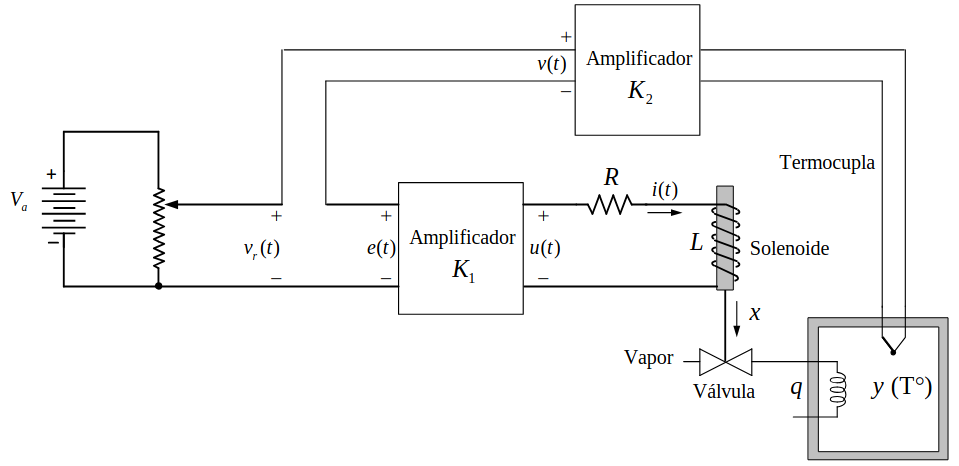

## Punto A

Indicar las partes del sistema de control; planta, actuador, controlador y sensor

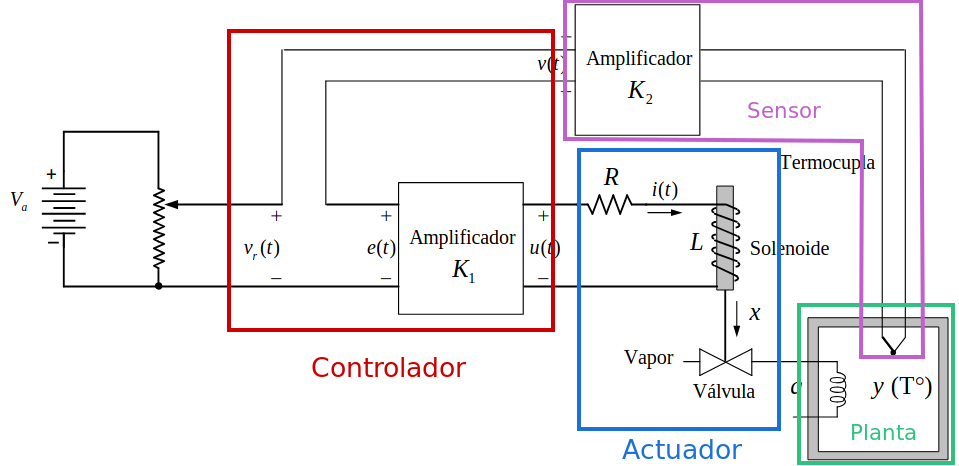

## Punto B

Para cada una de las partes mencionadas, expresar las ecuaciones temporales que intervienen y luego hallar las respectivas funciones de transferencias.

### Ecuaciones Temporales

#### Planta


$$\frac{dy}{dt} = -C \cdot y(t) + K_c \cdot q(t)$$



$$q(t) = K_q \cdot x(t)$$


#### Actuador


$$u(t) = R \cdot i(t) + L \cdot \frac{di(t)}{dt}$$



$$x(t) = K_s \cdot i(t)$$


#### Sensor


$$v(t) = K_2 \cdot y(t)$$


#### Controlador


$$e(t) = v_r(t) - v(t)$$



$$u(t) = K_1 \cdot e(t)$$


### Funciones de Transferencia

#### Planta


$$s \cdot Y(s) = -C \cdot Y(s) + K_c \cdot Q(s)$$



$$Y(s) \cdot (s + C) = K_c \cdot Q(s)$$



$$\frac{Y(s)}{Q(s)} = \frac{K_c}{s + C}$$



$$Q(s) = K_q \cdot X(s)$$



$$\frac{Q(s)}{X(s)} = K_q$$


#### Actuador


$$U(s) = R \cdot I(s) + L \cdot sI(s)$$



$$\frac{U(s)}{I(s)} = R + sL$$



$$X(s) = K_s \cdot I(s)$$



$$\frac{X(s)}{I(s)} = K_s$$


#### Sensor


$$V(s) = K_2 \cdot Y(s)$$



$$\frac{V(s)}{Y(s)} = K_2$$


#### Controlador


$$E(s) = V_r(s) - V(s)$$



$$U(s) = K_1 \cdot E(s)$$



$$U(s) = K_1 \cdot (V_r(s) - V(s))$$


## Punto C

A partir de cada una de las funciones de transferencias halladas en el punto anterior, hacer un diagrama en bloques del sistema de control temperatura a lazo cerrado indicando las señales que intervienen y cada una de las funciones mencionadas dentro de los bloques.

%open_system("tp1ej1pC.slx")

## Punto D

Teniendo en cuenta el diagrama anterior, hallar la función de transferencia a lazo abierto en

el camino directo $G_{LA}(s)$ y función de transferencia a lazo cerrado $G_{LC}(s)$. Indicar la ganancia,

los ceros y los polos de las funciones $G_{LA}(s)$ y $G_{LC}(s)$.

#### Lazo Abierto


$$G_{LA}(s) = \frac{Y(s)}{V_r(s)} =  \frac{K_1 \cdot K_s \cdot K_q \cdot K_c}{L \cdot (s + RL^{-1}) \cdot (s + C)$$


Gananacia: $H_0 = \frac{K_1 \cdot K_s \cdot K_q \cdot K_c}{L}$

Ceros: No tiene

Polos: $p_1 = -C$ y $p_2 = -RL^{-1}$

#### Lazo Cerrado


$$G_{LC}(s) = \frac{G_{LA}(s)}{1+H(s)G_{LA}(s)} = \frac{K_1 \cdot K_s \cdot K_q \cdot K_c \cdot L^{-1}}{s^2+s(RL^{-1}+C) + RCL^{-1} + K_1 K_2 K_s K_q K_c L^{-1}$$


Ganancia: $H_0 = K_1 \cdot K_s \cdot K_q \cdot K_c \cdot L^{-1}$

Ceros: No tiene

Polos:

syms s K1 K2 Ks Kq Kc R L C;
den = s^2 + s * ((R / L) + C) + R * C / L + K1 * K2 * Ks * Kq * Kc / L;
solve(den == 0, s)

$$ans = \left(\begin{array}{c} -\frac{R+\sqrt{C^{2}\,L^{2}-2\,C\,L\,R-4\,K_{1}\,K_{2}\,\mathrm{Kc}\,\mathrm{Kq}\,\mathrm{Ks}\,L+R^{2}}+C\,L}{2\,L}\\ -\frac{R-\sqrt{C^{2}\,L^{2}-2\,C\,L\,R-4\,K_{1}\,K_{2}\,\mathrm{Kc}\,\mathrm{Kq}\,\mathrm{Ks}\,L+R^{2}}+C\,L}{2\,L} \end{array}\right)$$

## Punto E

Considerando:

K1 = 100; %V/V
K2 = 1; %V/degC
Kq = 1; %kg/sm
Ks = 1; %m/A
Kc = 1; %degC/(kg/m)
R = 100; %ohm
L = 0.01 * 10^-3; %H
C = 0.25; %degC^-1

Hallar las funciones de transferencia mencionadas en el punto anterior, indicando ganancia, ceros y polos.

#### Lazo Abierto

Función de transferencia:

Z = [];
P = [-R/L -C];
K = K1*Kq*Ks*Kc/L;
GLA = tf(zpk(Z, P, K));

Ganancia:

[z, p, k] = zpkdata(zpk(GLA));
k

k = 10000000

Ceros: No tiene

Polos:

p{1}(1)

ans = -10000000

p{1}(2)

ans = -0.2500

#### Lazo Cerrado

Funcion de transferencia:

GLC = feedback(GLA, K2, -1)

GLC =
 
           1e07
  ----------------------
  s^2 + 1e07 s + 1.25e07
 
Continuous-time transfer function.
Model Properties


zpk(GLC)

ans =
 
        1e+07
  -----------------
  (s+1e07) (s+1.25)
 
Continuous-time zero/pole/gain model.
Model Properties


Ganancia: $1\times 10^7$

Ceros: No tiene

Polos: $-1\times 10^7$ y $-0.25$

## Punto F

t = 0:0.001:25;
vref = 10 * ones(length(t),1);

### Respuesta temporal

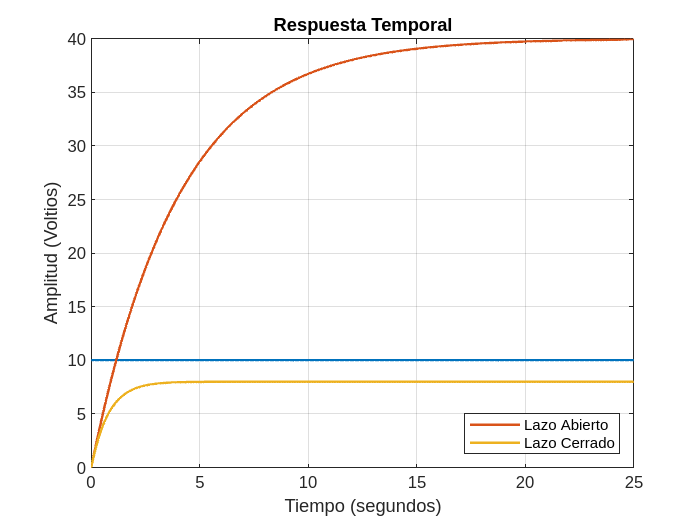

[yla, t] = lsim(GLA, vref, t);
[ylc, t] = lsim(GLC, vref, t);
figure
plot(t, [vref, yla, ylc], 'LineWidth', 1.5)
title 'Respuesta Temporal'
xlabel 'Tiempo (segundos)'
ylabel 'Amplitud (Voltios)'
grid on
legend("","Lazo Abierto","Lazo Cerrado", "Location", "southeast")

### Respuestas de magnitud y fase

#### Lazo Abierto

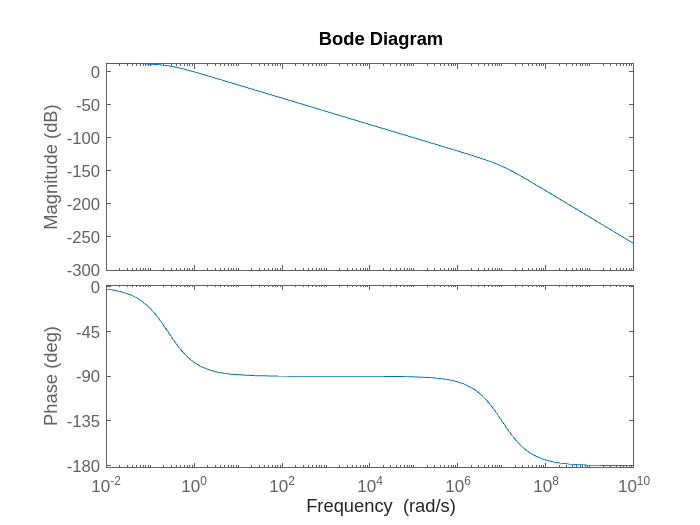

bode(GLA, {1e-2, 1e10})

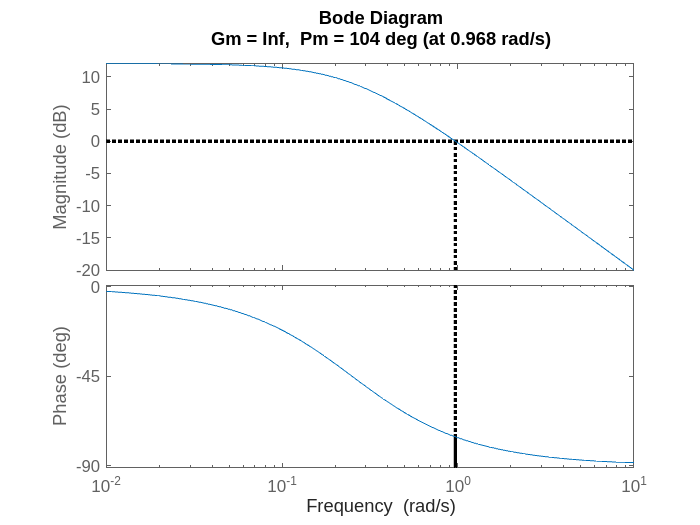

margin(GLA)

#### Lazo Cerrado

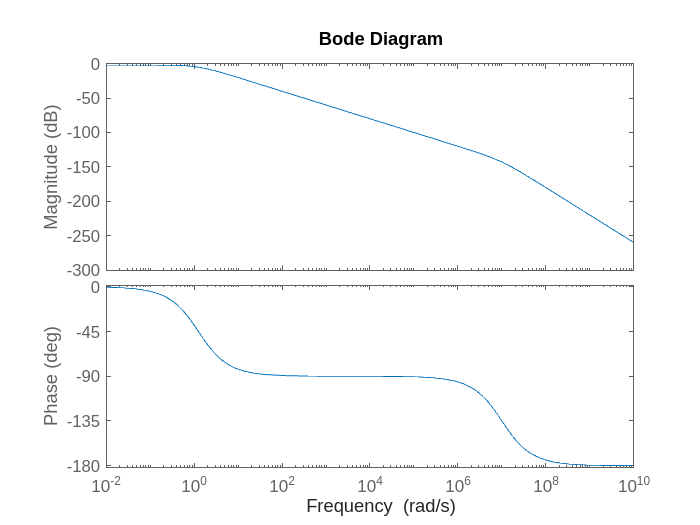

bode(GLC, {1e-2, 1e10})

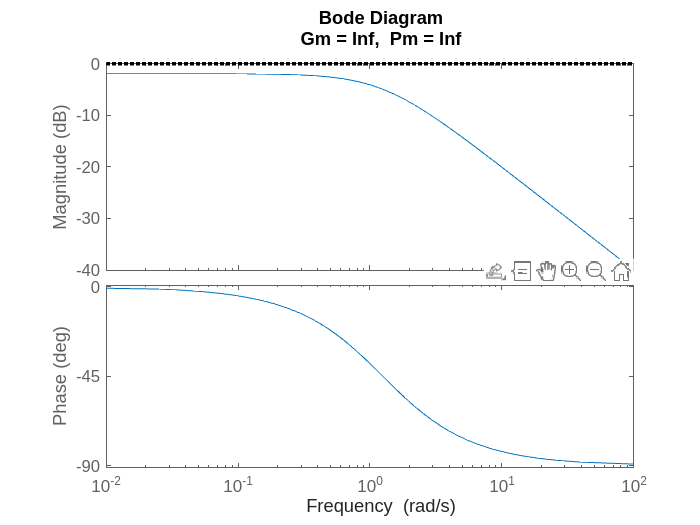

margin(GLC)

## Punto G

Teniéndose en cuenta que la cámara no es totalmente adiabática y puede alterarse la temperatura interna por pérdida de calor, se tiene en cuenta este efecto en la siguiente ecuación con una componente de perturbación $Q_p(t)$. 


$$\frac{dy}{dt} = -Cy(t) + K_c q(t) - K_c Q_p(t)$$
 

Incorpore en el diagrama de bloques de lazo cerrado esta perturbación; escriba la ecuación de la salida Y(s) incluyendo la misma; analice su efecto en la respuesta de salida ante una aplicación en escalón de $Q_p(t) = 2 kg$ con $Vr(t) = 0 V$ y finalmente analice el efecto en la respuesta de $y(t)$, combinando ambos efectos con $V_r(t) = 10 V$.

#### Ecuación de salida


$$sY(s) = -C Y(s) + K_c Q(s) - K_c Q_p(s)$$



$$Y(s) (s + C) = K_c (Q(s) - Q_p(s))$$



$$Y(s) = K_c \frac{Q(s) - Q_p(s)}{s+C}$$


#### Respuesta de Salida

%open_system("tp1ej1pG")